1- getting vectors of y and u:

warning off
[y,u] = HW1_sensor(810198356);

y_train = y(1:70);
y_test = y(71:100);
u_train = u(1:70);
u_test = u(71:100);

3- finding n from inverse of z transform:

finding y_Ls:

for n = 4:30
    y_train_n = y_train(n:70);
    transpose_y = transpose(y_train_n);
    
    phi_output = zeros(70-n+1,n-1);
    for i = n:70
        for j = 1:n-1
            phi_output(i-(n-1),j) = -y_train(i-j);
        end
    end
    
    phi_input = zeros(70-n+1,3);
    for i = n:70
        phi_input(i-(n-1),1) = u_train(i);
        phi_input(i-(n-1),2) = u_train(i-1);
        phi_input(i-(n-1),3) = u_train(i-3);
    end
    
    phi = [phi_output phi_input];
    theta = inv(transpose(phi) * phi) * transpose(phi) * transpose_y;
    y_Ls = phi * (theta);
    j_train(1,n-3) = norm(y_train_n - y_Ls)^2;
end

calculating j for test data:

for n = 4:30
    y_test_n = y_test(n:30);
    transpose_y_test = transpose(y_test_n);
    
    phi_output_test = zeros(30-n+1,n-1);
    for i = n:30
        for j = 1:n-1
            phi_output_test(i-(n-1),j) = -y_test(i-j);
        end
    end
    
    phi_input_test = zeros(30-n+1,3);
    for i = n:30
        phi_input_test(i-(n-1),1) = u_test(i);
        phi_input_test(i-(n-1),2) = u_test(i-1);
        phi_input_test(i-(n-1),3) = u_test(i-3);
    end
    
    phi_test = [phi_output_test phi_input_test];
    theta_test = inv(transpose(phi_test) * phi_test) * transpose(phi_test) * transpose_y_test;
    y_Ls_test = phi_test * (theta_test);
    
    j_test(1,n-3) = norm(y_test_n - y_Ls_test)^2;
end

j_train

j_train = 	1.0e+11 *

    0.0037    0.0036    0.0035    0.0034    0.0033    0.0032    0.0031    0.0031    0.0029    0.0028    0.0028    0.0027    0.0059    0.0122    0.0025    0.0024    0.0028    0.0031    0.0049    0.0020    0.0025    0.0032    0.0047    0.0017    0.0153    0.0116    3.3311


j_test

j_test = 	1.0e+09 *

    0.0530    0.0509    0.0439    0.0393    0.0370    0.0354    0.0306    0.0253    0.0236    0.0297    0.0230    0.1033    0.2536    0.0354    0.0150    0.0171    0.0423    0.0076    1.2675    0.0983    0.8942    0.0644    1.4739    0.3509    0.0020    0.0027    0.0459


x = 4:30

x =      4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


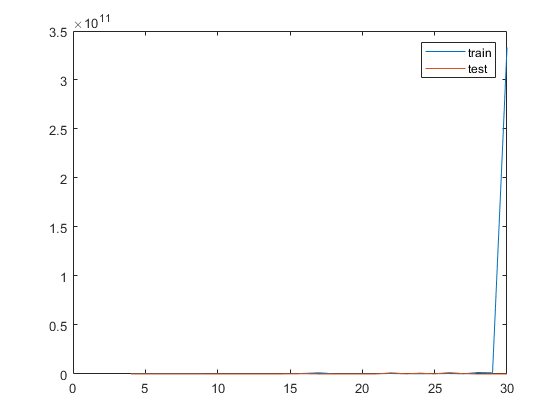

cofactor_matrix =    11.4552
    2.4882
  -22.7038
   14.4928
    3.8906
   -4.4448
    3.1397
   -6.2304
    2.8848
    4.0570


plot(x,j_train)
hold on
plot(x,j_test)
legend("train","test")
hold off